omnih5= 'G:\My Drive\Research\Projects\Data\omni.h5';

time = h5read(omnih5,'/Time');
time = unixtime2matlab(time);

AL = h5read(omnih5,'/Indices/AL');

AU = h5read(omnih5,'/Indices/AU');

Kp = h5read(omnih5,'/Indices/Kp');

Dst = h5read(omnih5,'/Indices/SYM_H');

timeMinIndx = find_time(time,'01 Jan 2001');
timeMaxIndx = find_time(time,'31 Dec 2017');
tRange = timeMinIndx:timeMaxIndx;

[AL_n,AL_bin] = histcounts(AL(tRange),-3000:1:200,'Normalization','countdensity');
[AU_n,AU_bin] = histcounts(AU(tRange),-500:1:1500,'Normalization','countdensity');
Kp1 = Kp(timeMinIndx:timeMaxIndx);
Kpx = unique(Kp1(~isnan(Kp1)));
Kpx(end+1)=nan;
C = categorical(Kp1,Kpx,{'0_o ','0_+','1_-','1_o','1_+','2_-','2_o','2_+','3_-','3_o ','3_+','4_-','4_o','4_+',...
    '5_-','5_o','5_+','6_-','6_o','6_+','7_-','7_o','7_+','8_-','8_o','8_+','9_-','9_o','NaN'});
[Kp_n,Kp_bin] = histcounts(C,'Normalization','countdensity');
[Dst_n,Dst_bin] = histcounts(Dst(tRange),-500:1:200,'Normalization','countdensity');


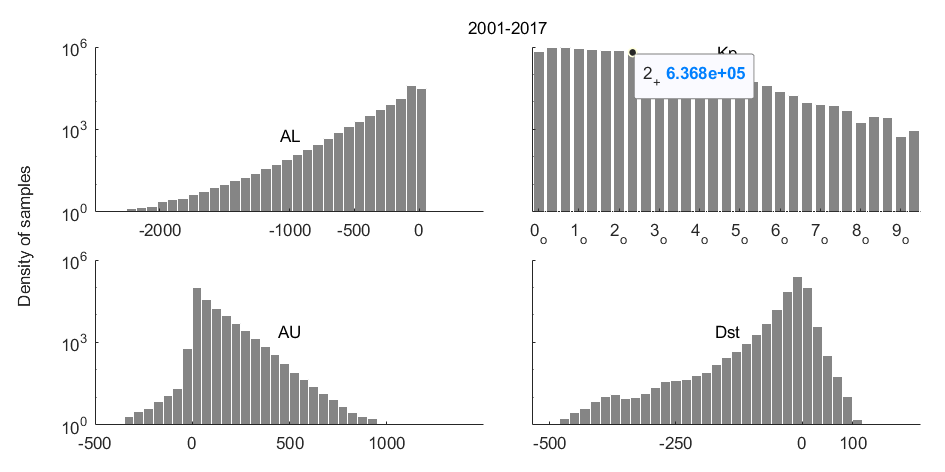

h=figure;
resize_figure(h,100,200);
p=panel();
p.pack(2,2);
p.de.margin=10;
p.marginbottom=10;
p.margintop=10;
p.marginleft=20;
p.select('all');
tt=p.title('2001-2017');
tt.FontSize=24;
darkGrey = [0.2 0.2 0.2];
p.ylabel('Density of samples');
p(1,1).select();
% plot(AL_bin(1:end-1),AL_n,'-r');
histogram(AL(tRange),-2500:80:500,'Normalization','countdensity','EdgeColor','white','FaceColor',darkGrey);
set(gca,'YScale','log','YLim',[1,10^6],'YTick',[1,1000,10^6],'XTick',[-2000,-1000,-500,0],'XLim',[-2500,500]);
t=title('AL','Units','normalized','Position',[0.5,0.4,0]);
p(2,1).select();
% plot(AU_bin(1:end-1),AU_n,'-r');
histogram(AU(tRange),-500:50:1500,'Normalization','countdensity','EdgeColor','white','FaceColor',darkGrey);
set(gca,'YScale','log','YLim',[1,10^6],'YTick',[1,1000,10^6],'XLim',[-500,1500],'XTick',[-500,0,500,1000]);
t=title('AU','Units','normalized','Position',[0.5,0.5,0]);

p(1,2).select();
% plot(Kp_n(1:end-1),'-r');
histogram(C,'Normalization','countdensity','EdgeColor','white','FaceColor',darkGrey,'BarWidth',0.8);
set(gca,'YScale','log','YLim',[1,10^6],'YTick',[1,1000,10^6],'YTickLabel','',...
    'XTick',{'0_o','1_o','2_o','3_o','4_o','5_o','6_o','7_o','8_o','9_o'});
% set(gca,'YScale','log','YLim',[1,10^6],'YTick',[1,1000,10^6],'XTick',1:3:length(Kp_bin)-1,'XtickLabel', cellstr(Kp_bin(1:3:length(Kp_bin)-1)));
t=title('Kp','Units','normalized','Position',[0.5,0.9,0]);

p(2,2).select();
% plot(Dst_bin(1:end-1),Dst_n,'-r');
histogram(Dst(tRange),-500:20:200,'Normalization','countdensity','EdgeColor','white','FaceColor',darkGrey);
set(gca,'YScale','log','YLim',[1,10^6],'YTick',[1,1000,10^6],'YTickLabel','',...
    'XTick',[-500,-250,0,100]);
t=title('Dst','Units','normalized','Position',[0.5,0.5,0]);

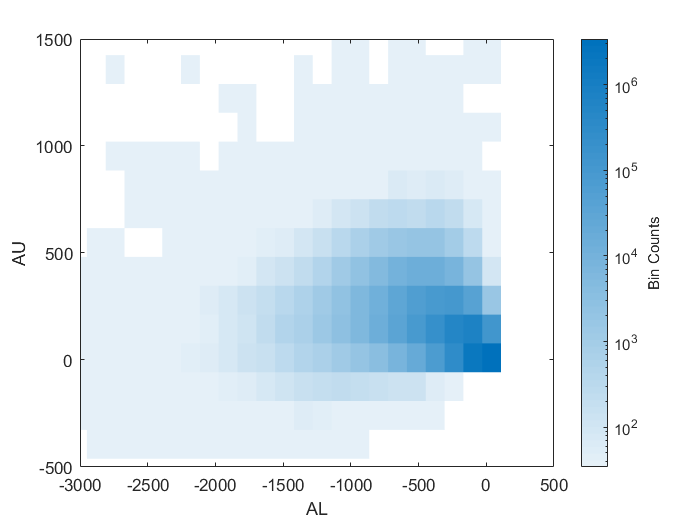

figure;
binscatter(AL(tRange),AU(tRange));
xlabel('AL');ylabel('AU');
ax = gca;
ax.ColorScale = 'log';
set(ax,'XLim',[-3000,500],'YLim',[-500,1500]);

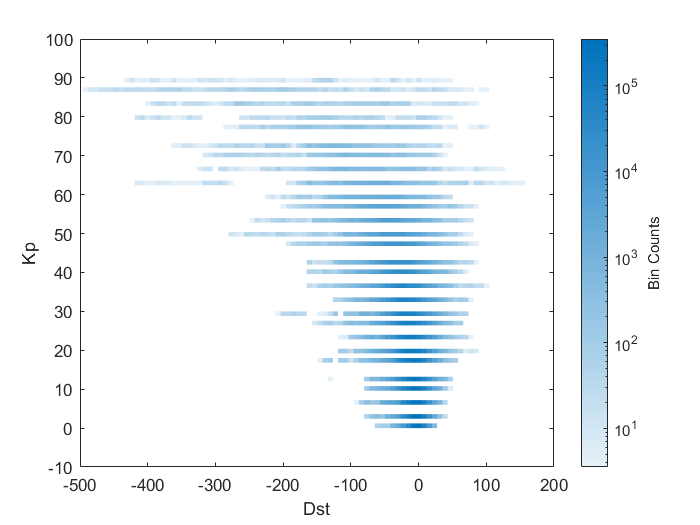

figure;
binscatter(Dst(tRange),Kp(tRange));
ax = gca; xlabel('Dst');ylabel('Kp');
ax.ColorScale = 'log';
set(ax,'XLim',[-500,200],'YLim',[-10,100]);

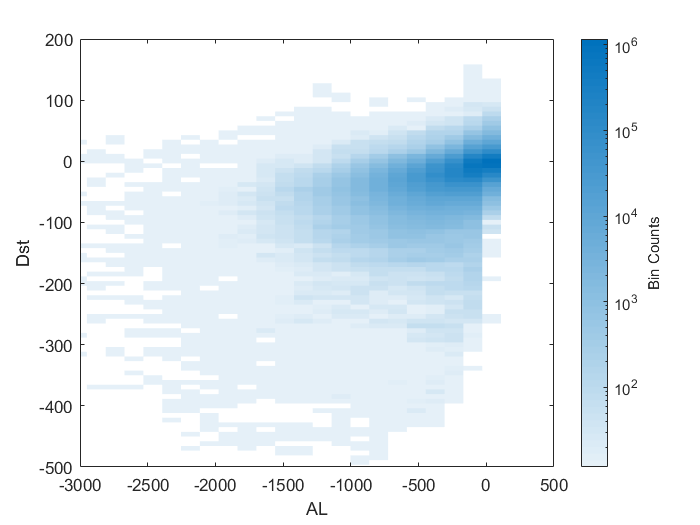

figure;
binscatter(AL(tRange),Dst(tRange));
ax = gca; xlabel('AL');ylabel('Dst');
ax.ColorScale = 'log';
set(ax,'XLim',[-3000,500],'YLim',[-500,200]);

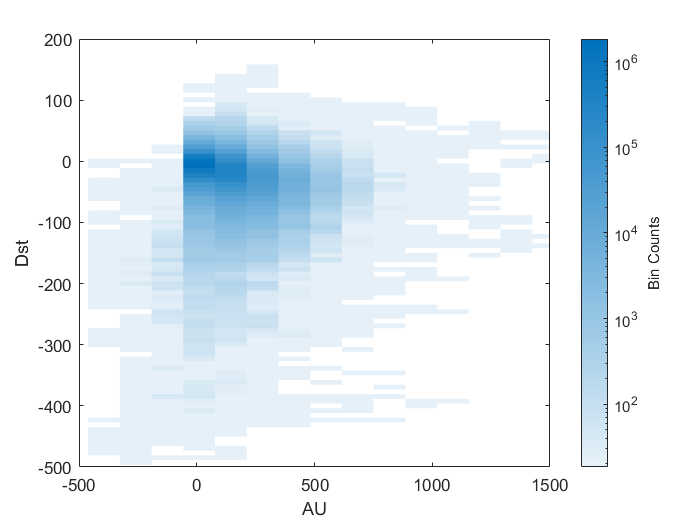

figure;
binscatter(AU(tRange),Dst(tRange));
ax = gca; xlabel('AU');ylabel('Dst');
ax.ColorScale = 'log';
set(ax,'XLim',[-500,1500],'YLim',[-500,200]);

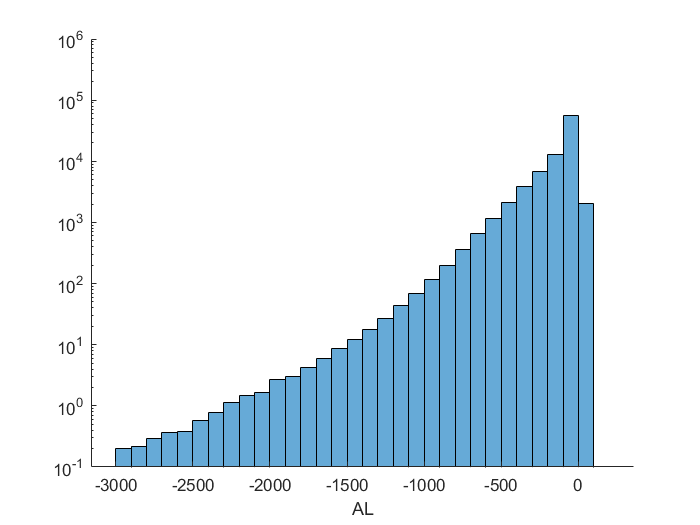


figure;
AL1 = AL(timeMinIndx:timeMaxIndx);
h=histogram(AL1(AL1<1000 & AL1>-3000),-3000:100:200,'DisplayStyle','bar','Normalization','countdensity');  
h.LineWidth = 0.1;
box off
set(gca,'YScale','log','YLim',[0.1,10^6]);
xlabel('AL');

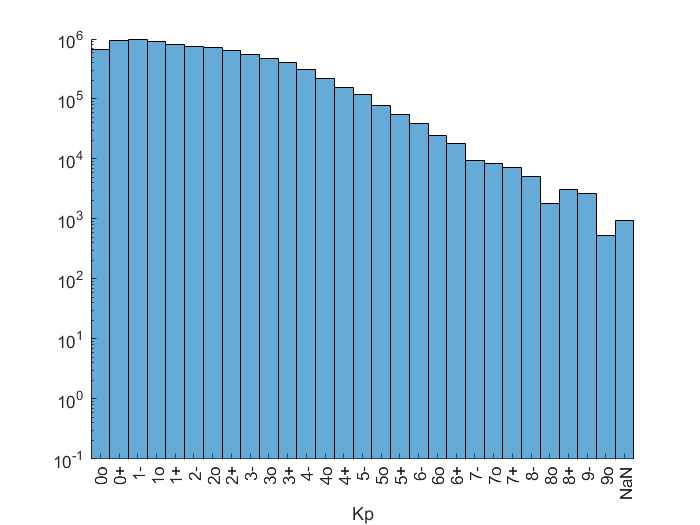

figure;
Kp1 = Kp(timeMinIndx:timeMaxIndx);
Kpx = unique(Kp1(~isnan(Kp1)));
Kpx(end+1)=nan;
C = categorical(Kp1,Kpx,{'0o ','0+','1-','1o','1+','2-','2o','2+','3-','3o ','3+','4-','4o','4+',...
    '5-','5o','5+','6-','6o','6+','7-','7o','7+','8-','8o','8+','9-','9o','NaN'});
histogram(C,'BarWidth',1);
box off;
set(gca,'YScale','log','YLim',[0.1,10^6]);
xlabel('Kp');

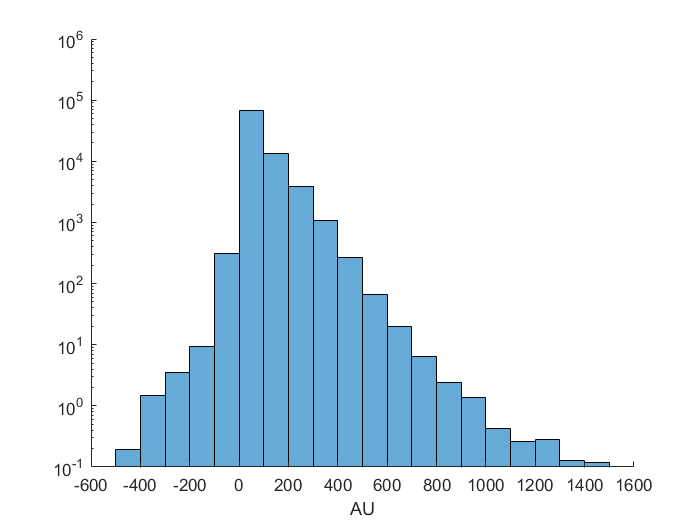

figure;
AU1 = AU(timeMinIndx:timeMaxIndx);
h=histogram(AU1(AU1<3000 & AU1>-3000),-500:100:1500,'DisplayStyle','bar','Normalization','countdensity');  
box off
set(gca,'YScale','log','YLim',[0.1,10^6]);
xlabel('AU');

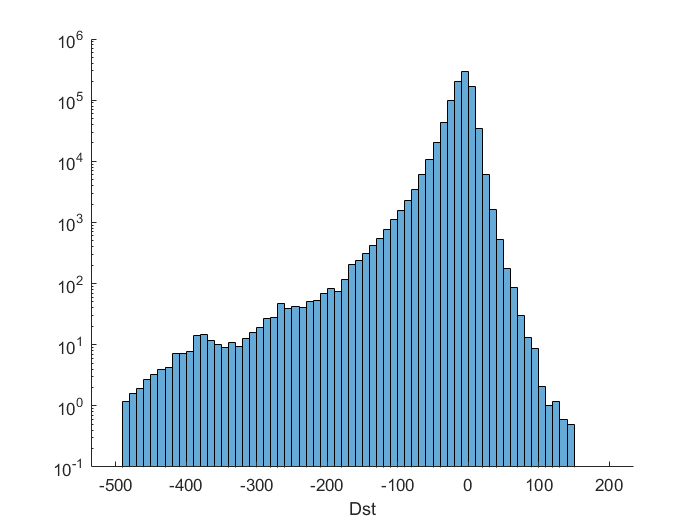

figure;
Dst1 = Dst(timeMinIndx:timeMaxIndx);
h=histogram(Dst1(Dst1<3000 & Dst1>-3000),-500:10:200,'DisplayStyle','bar','Normalization','countdensity');  
box off
set(gca,'YScale','log','YLim',[0.1,10^6]);
xlabel('Dst');